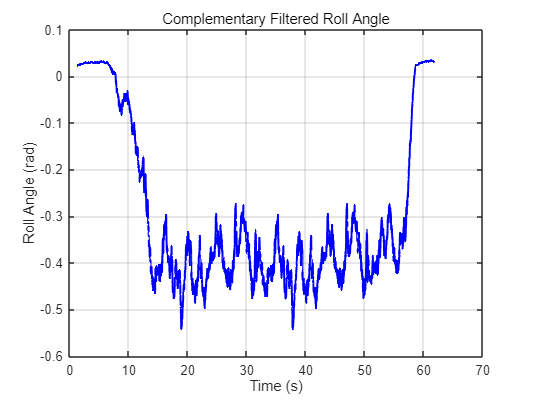

%% Load IMU Data
data = readtable('imu1.csv');
t = data.Time_ms / 1000;  % sec
dt = mean(diff(t));       % sampling time

Gx = data.GyroX_degps;    % deg/s
Gy = data.GyroY_degps;
Gz = data.GyroZ_degps;

Ax = data.AccelX_g * 9.80665;
Ay = data.AccelY_g * 9.80665;
Az = data.AccelZ_g * 9.80665;

%% Convert Gyro to rad/s
Gy_rad = Gy * pi/180;

%% Accelerometer-based Roll (static inclination angle)
acc_roll = atan2(Ay, Az);   % rad

%% Complementary Filter
alpha = 0.98;  % 자이로 우선도 (0.95~0.99 사이 실험 추천)
roll = zeros(size(t));
roll(1) = acc_roll(1);  % 초기값은 가속도 기반

for i = 2:length(t)
    gyro_integration = roll(i-1) + Gy_rad(i) * dt;
    roll(i) = alpha * gyro_integration + (1 - alpha) * acc_roll(i);
end

%% 시각화
figure;
plot(t, roll, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Roll Angle (rad)');
title('Complementary Filtered Roll Angle');
grid on;